# Script for varying P1

## Varying P1

clear
clc

pa = linspace(1,101325,25); %ambient pressure
Ta = 210; %ambient temperature
Mf = 2.8; %free stream mach number
Shock = 1.1; %normal shock strength (before shock mach number)
Mbe = 0.2; %burner entry mach number
Tb = 1700; %maximum burner temperature
bpr = 1; %burner pressure ratio
epr = 1; %exhaust pressure ratio
thrust = 5e5; %required thrust

for i = 1 : length(pa)
    [A1(i), At1(i), Abe(i), Abx(i), At3(i), Ae(i), thermeff(i), propeff(i)] = ramjet(pa(i),Ta,Mf,Shock,Mbe,Tb,bpr,epr,thrust);
end

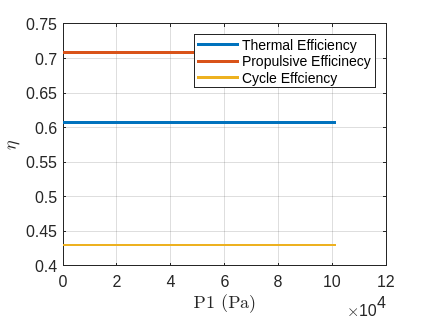

% efficiencies
figure(1)
plot(pa,thermeff,'LineWidth',2)
hold on
plot(pa,propeff,'LineWidth',2)
plot(pa,propeff.*thermeff,'LineWidth',2)
hold off
grid on
xlabel('P1 (Pa)','Interpreter','latex')
ylabel('$\eta$','Interpreter','latex')
legend('Thermal Efficiency','Propulsive Efficinecy','Cycle Effciency')
set(gca,'FontSize',12)

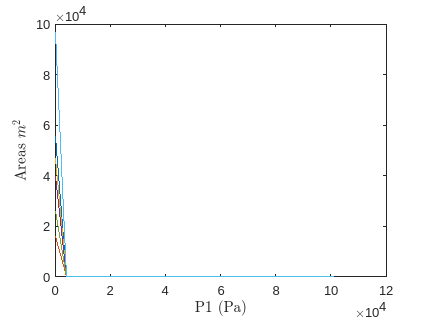


% Areas
figure(2)
plot(pa,A1)
hold on
plot(pa,At1)
plot(pa,Abe)
plot(pa,Abx)
plot(pa,At3)
plot(pa,Ae)
hold off
xlabel('P1 (Pa)','Interpreter','latex')
ylabel('Areas $m^2$','Interpreter','latex')